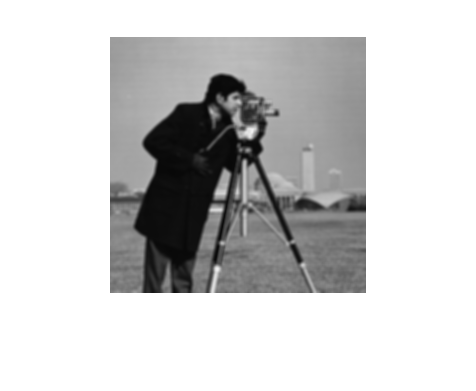

clear;
img = imread('cameraman.tif');

% Gussian Filter
g_filtered = imgaussfilt(img, 1.6, 'FilterSize', 5);
imshow(g_filtered)

title('Gaussian-filtered Cameraman')
m_pyramid(g_filtered, 'gaussian')

gaussian128x128.bmp
Saved in the working directory.
gaussian64x64.bmp
Saved in the working directory.
gaussian32x32.bmp
Saved in the working directory.
gaussian16x16.bmp
Saved in the working directory.
gaussian8x8.bmp
Saved in the working directory.
gaussian4x4.bmp
Saved in the working directory.
gaussian2x2.bmp
Saved in the working directory.
gaussian1x1.bmp
Saved in the working directory.


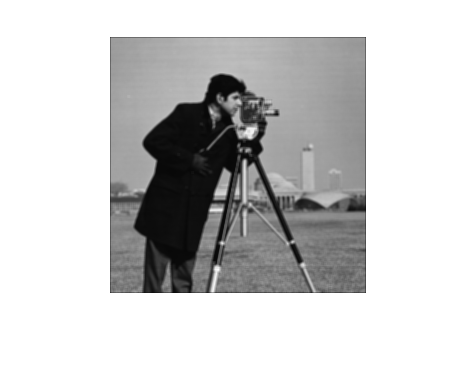


% Average Filter
m_filtered = uint8(mean_filter(img, 3));
imshow(m_filtered)

title('Mean-filtered Cameraman')
m_pyramid(m_filtered, 'mean')

mean128x128.bmp
Saved in the working directory.
mean64x64.bmp
Saved in the working directory.
mean32x32.bmp
Saved in the working directory.
mean16x16.bmp
Saved in the working directory.
mean8x8.bmp
Saved in the working directory.
mean4x4.bmp
Saved in the working directory.
mean2x2.bmp
Saved in the working directory.
mean1x1.bmp
Saved in the working directory.



% Laplacian Filter
laplacian_pyramid(g_filtered, 'laplacian');

laplacian128x128.bmp
Saved in the working directory.
laplacian64x64.bmp
Saved in the working directory.
laplacian32x32.bmp
Saved in the working directory.
laplacian16x16.bmp
Saved in the working directory.
laplacian8x8.bmp
Saved in the working directory.
laplacian4x4.bmp
Saved in the working directory.
laplacian2x2.bmp
Saved in the working directory.
laplacian1x1.bmp
Saved in the working directory.
laplacian1x1.bmp
Saved in the working directory.


# External Functions

function m_pyramid(arg, arg2)

[x, y] = size(arg);

if x~=y
    error('Image is not square.');
end

out = uint8(impyramid(arg, 'reduce'));
imwrite(out, strcat(arg2, int2str(x/2), 'x', int2str(x/2),'.bmp'));
disp(strcat(arg2, int2str(x/2), 'x', int2str(x/2),'.bmp'))
disp('Saved in the working directory.')

if size(out, 1) > 1
    m_pyramid(out, arg2)
end

end

function out = mean_filter(arg, kernel_size)

kernel = ones(kernel_size, kernel_size) ./ (kernel_size*kernel_size);
out = conv2(arg, kernel, 'same');

end

function laplacian_pyramid(arg, arg2)

[x, y] = size(arg);

if x~=y
    error('Image is not square.');
end

reduced = uint8(impyramid(arg, 'reduce'));
upsampled = uint8(imresize(reduced,[x y]));
out = arg - upsampled;

imwrite(out, strcat(arg2, int2str(x/2), 'x', int2str(x/2),'.bmp'));
disp(strcat(arg2, int2str(x/2), 'x', int2str(x/2),'.bmp'))
disp('Saved in the working directory.')

if size(out, 1) > 1
    laplacian_pyramid(reduced, arg2)
end

end